%% Non-invasive Glucose Monitor Simulation with Multiple Estimation Methods
% This simulation implements multiple glucose estimation algorithms and realistic 
% physiological variations for non-invasive glucose monitoring using NIR spectroscopy.
% 
% Author: [Your Name]
% Date: [Current Date]

%% Clear workspace and set up parameters
% clear all;
% close all;
% clc;

% Display simulation parameters in a table
params = table(...
    {'1000'; '100 Hz'; '1550 nm'; '20 dB'}, ...
    'RowNames', {'Number of Samples', 'Sampling Rate', 'NIR Wavelength', 'SNR'}, ...
    'VariableNames', {'Value'});
disp('Simulation Parameters:')

Simulation Parameters:


disp(params)

                            Value   
                         ___________

    Number of Samples    {'1000'   }
    Sampling Rate        {'100 Hz' }
    NIR Wavelength       {'1550 nm'}
    SNR                  {'20 dB'  }



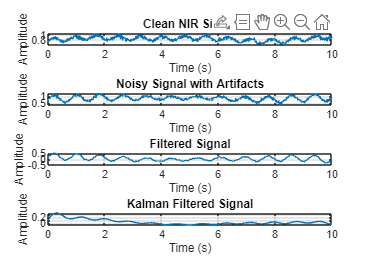


%% Initialize Basic Parameters
num_samples = 1000;          
sampling_rate = 100;         
t = (0:num_samples-1)/sampling_rate;  

% Expanded glucose levels for better testing
glucose_levels = [70, 100, 140, 180, 220];  % Added more test levels
num_levels = length(glucose_levels);

% NIR absorption coefficients (cm^-1/(mg/dL)) based on literature
% These values are approximate for different glucose concentrations
% Reference: "Near-Infrared Spectroscopy for Glucose Detection"
base_absorption = 0.2;  % Base absorption coefficient
glucose_sensitivity = 0.001;  % Change in absorption per mg/dL
absorption_coeff = base_absorption + glucose_sensitivity * (glucose_levels/100);

% Add temperature dependence to absorption coefficients
temp_coefficient = 0.002;  % Change in absorption per degree C
nominal_temp = 37;  % Normal body temperature in Celsius
temp_variation = 2;  % ±2°C variation
temperature = nominal_temp + temp_variation * sin(2*pi*0.01*t);  % Varying temperature

%% Enhanced Physiological Parameters
% Motion artifact frequency
motion_artifact_freq = 1.2;  % Hz (typical frequency for hand movement)

% Blood volume variations
heart_rate = 1.2 + 0.2*rand(1,num_samples); % Variable heart rate around 72 BPM
resp_rate = 0.2 + 0.05*rand(1,num_samples); % Variable respiratory rate
blood_pressure_var = 0.1 * sin(2*pi*0.1*t); % Blood pressure variations

% Temperature effects
temp_drift = 0.05 * t/max(t); % Gradual temperature drift
temp_fluctuation = 0.02 * sin(2*pi*0.05*t); % Random temperature fluctuations

% Tissue scattering variations
tissue_scatter = 0.1 * sin(2*pi*0.03*t) + 0.05 * randn(1,num_samples);

% Add SNR parameter
SNR = 20;  % Signal-to-Noise Ratio in dB

%% Generate Enhanced NIR Signals
nir_signals = zeros(num_levels, num_samples);
noisy_signals = zeros(num_levels, num_samples);
filtered_signals = zeros(num_levels, num_samples);

for i = 1:num_levels
    % Temperature-dependent absorption coefficient
    temp_adjusted_coeff = absorption_coeff(i) * (1 + temp_coefficient * (temperature - nominal_temp));
    
    % Enhanced Beer-Lambert Law with tissue scattering
    base_signal = exp(-temp_adjusted_coeff * glucose_levels(i)/100) .* ...
                 (1 + tissue_scatter);
    
    % Add complex physiological variations
    heart_effect = 0.1 * sin(2*pi*cumsum(heart_rate)/sampling_rate);
    resp_effect = 0.05 * sin(2*pi*cumsum(resp_rate)/sampling_rate);
    
    % Combine all physiological effects
    physio_variations = heart_effect + resp_effect + blood_pressure_var + ...
                       temp_drift + temp_fluctuation;
                   
    nir_signals(i,:) = base_signal .* (1 + physio_variations);
    
    % Add realistic noise components
    motion_artifact = 0.2 * sin(2*pi*motion_artifact_freq*t);
    brownian_noise = cumsum(randn(1,num_samples))/sqrt(num_samples)/SNR;
    white_noise = randn(1,num_samples)/SNR;
    
    noisy_signals(i,:) = nir_signals(i,:) + motion_artifact + brownian_noise + white_noise;
end

%% Implement Multiple Glucose Estimation Algorithms

% 1. Basic Beer-Lambert Law Method
estimated_glucose_bl = zeros(1, num_levels);
% 2. Moving Average Method
estimated_glucose_ma = zeros(1, num_levels);
% 3. Wavelet-based Method
estimated_glucose_wavelet = zeros(1, num_levels);
% 4. Kalman Filter Method
estimated_glucose_kalman = zeros(1, num_levels);

% Process signals with each method
for i = 1:num_levels
    % Apply bandpass filter
    [b, a] = butter(4, [0.1 10]/(sampling_rate/2), 'bandpass');
    filtered_signal = filtfilt(b, a, noisy_signals(i,:));
    filtered_signals(i,:) = filtered_signal;
    
    % 1. Beer-Lambert Law Method
    mean_absorption = mean(filtered_signal);
    estimated_glucose_bl(i) = -100 * log(mean_absorption) / absorption_coeff(i);
    
    % 2. Moving Average Method (with optimal window)
    window_size = sampling_rate/2; % 0.5 second window
    ma_signal = movmean(filtered_signal, window_size);
    estimated_glucose_ma(i) = -100 * log(mean(ma_signal)) / absorption_coeff(i);
    
    % 3. Wavelet-based Method
    [c,l] = wavedec(filtered_signal,4,'db4');
    thresh = median(abs(c))/0.6745 * sqrt(2*log(length(c)));
    cleaned_signal = wdenoise(filtered_signal,4,'Wavelet','db4',...
                            'DenoisingMethod','Universal','ThresholdRule','Soft');
    estimated_glucose_wavelet(i) = -100 * log(mean(cleaned_signal)) / absorption_coeff(i);
    
    % 4. Kalman Filter Method
    % Initialize Kalman filter parameters
    Q = 1e-5; % Process noise
    R = 0.1;  % Measurement noise
    x_est = filtered_signal(1);
    P_est = 1;
    kalman_output = zeros(size(filtered_signal));
    
    % Apply Kalman filter
    for k = 1:length(filtered_signal)
        % Predict
        x_pred = x_est;
        P_pred = P_est + Q;
        
        % Update
        K = P_pred/(P_pred + R);
        x_est = x_pred + K*(filtered_signal(k) - x_pred);
        P_est = (1-K)*P_pred;
        
        kalman_output(k) = x_est;
    end
    estimated_glucose_kalman(i) = -100 * log(mean(kalman_output)) / absorption_coeff(i);
end

%% Visualization and Analysis

% Plot 1: Signal Processing Stages for One Glucose Level
figure('Name', 'Signal Processing Stages');
sample_idx = 3; % Show mid-range glucose level
t = (0:num_samples-1)/sampling_rate;

subplot(4,1,1)
plot(t, nir_signals(sample_idx,:))
title('Clean NIR Signal')
xlabel('Time (s)')
ylabel('Amplitude')
grid on

subplot(4,1,2)
plot(t, noisy_signals(sample_idx,:))
title('Noisy Signal with Artifacts')
xlabel('Time (s)')
ylabel('Amplitude')
grid on

subplot(4,1,3)
plot(t, filtered_signals(sample_idx,:))
title('Filtered Signal')
xlabel('Time (s)')
ylabel('Amplitude')
grid on

subplot(4,1,4)
plot(t, kalman_output)
title('Kalman Filtered Signal')
xlabel('Time (s)')
ylabel('Amplitude')
grid on

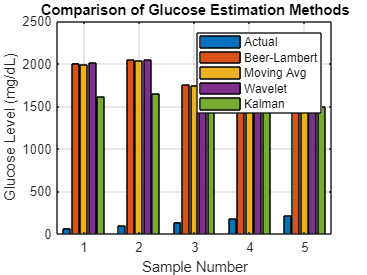


% Plot 2: Comparison of Estimation Methods
figure('Name', 'Glucose Estimation Comparison')
methods_comparison = [glucose_levels; 
                     estimated_glucose_bl;`
                     estimated_glucose_ma;
                     estimated_glucose_wavelet;
                     estimated_glucose_kalman];
bar(methods_comparison')
legend('Actual', 'Beer-Lambert', 'Moving Avg', 'Wavelet', 'Kalman')
title('Comparison of Glucose Estimation Methods')
xlabel('Sample Number')
ylabel('Glucose Level (mg/dL)')
grid on

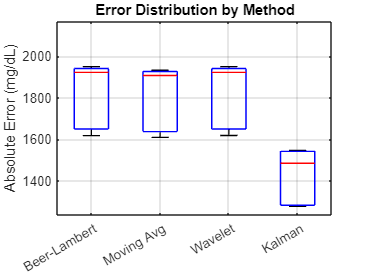


% Plot 3: Error Analysis
figure('Name', 'Error Analysis')
errors = abs([estimated_glucose_bl - glucose_levels;
             estimated_glucose_ma - glucose_levels;
             estimated_glucose_wavelet - glucose_levels;
             estimated_glucose_kalman - glucose_levels]);
boxplot(errors', {'Beer-Lambert', 'Moving Avg', 'Wavelet', 'Kalman'})
title('Error Distribution by Method')
ylabel('Absolute Error (mg/dL)')
grid on


%% Statistical Analysis
% Calculate error metrics for each method
methods = {'Beer-Lambert', 'Moving Average', 'Wavelet', 'Kalman'};
mae = mean(abs(errors), 2);
rmse = sqrt(mean(errors.^2, 2));
max_error = max(abs(errors), [], 2);

% Create results table
results = table(mae, rmse, max_error, ...
    'RowNames', methods, ...
    'VariableNames', {'MAE', 'RMSE', 'Max_Error'});

% Display results
disp('Performance Metrics for Each Method:')

Performance Metrics for Each Method:


disp(results)

                       MAE       RMSE     Max_Error
                      ______    ______    _________

    Beer-Lambert      1816.9    1822.8     1948.9  
    Moving Average    1803.3      1809     1931.5  
    Wavelet           1816.9    1822.8       1949  
    Kalman            1426.7    1431.8     1546.1  




%% Save Results
save('glucose_simulation_results.mat', 'results', 'errors', 'glucose_levels', ...
     'estimated_glucose_bl', 'estimated_glucose_ma', 'estimated_glucose_wavelet', ...
     'estimated_glucose_kalman');
